ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

us = {};
ds = {};

orientations = [0:45:315];
upPeakEx = [];
upPeakInh = [];
upCoordsEx = [];
upCoordsInh = [];


downPeakEx = [];
downPeakInh = [];
downCoordsEx = [];
downCoordsInh = [];

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass1 || ~pass2
        us(end+1, :) = ups(i, :);
    end
    
    
    if ~pass1
        loc = loc_excitation;
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        upCoordsEx = [upCoordsEx; x, y];
        
        thisResponse = [];
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            thisResponse = [thisResponse, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
        end
        upPeakEx = [upPeakEx;thisResponse];
    end
    
    if ~pass2
        loc = loc_inhibition;
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        upCoordsInh = [upCoordsInh; x, y];
        
        thisResponse = [];
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            thisResponse = [thisResponse, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
        end
        upPeakInh = [upPeakInh; thisResponse];
    end
end
%downs second
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass1 || ~pass2
        ds(end + 1,:) = downs(i, :);
    end
    
    if ~pass1
        loc = loc_excitation;
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        downCoordsEx = [downCoordsEx; x, y];
        
        thisResponse = [];
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            thisResponse = [thisResponse, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
        end
        downPeakEx = [downPeakEx; thisResponse];
    end
    
    if ~pass2
        loc = loc_inhibition;
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        downCoordsInh = [downCoordsInh; x, y];
        
        thisResponse = [];
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            thisResponse = [thisResponse, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
        end
        downPeakInh = [downPeakInh; thisResponse];
    end
end

## Partition By Location of Each Cell

%Coordinates of all cells used for excitation
xCoords_upEx = -upCoordsEx(:, 1); %make x coordinates negative because the manipulator gives opposite x coordinates on rig E
yCoords_upEx = upCoordsEx(:, 2);
xCoords_downEx = -downCoordsEx(:, 1);
yCoords_downEx = downCoordsEx(: , 2);

%store indices of each cell
dt_upEx = xCoords_upEx > 0 & yCoords_upEx > 0;
dt_downEx = xCoords_downEx > 0 & yCoords_downEx > 0;
dn_upEx = xCoords_upEx < 0 & yCoords_upEx > 0;
dn_downEx = xCoords_downEx < 0 & yCoords_downEx > 0;
vn_upEx = xCoords_upEx < 0 & yCoords_upEx < 0;
vn_downEx = xCoords_downEx < 0 & yCoords_downEx < 0;
vt_upEx = xCoords_upEx > 0 & yCoords_upEx < 0;
vt_downEx = xCoords_downEx > 0 & yCoords_downEx < 0;

%Repeat for inhibition
xCoords_upInh = -upCoordsInh(:, 1); %make x coordinates negative because the manipulator gives opposite x coordinates on rig E
yCoords_upInh = upCoordsInh(:, 2);
xCoords_downInh = -downCoordsInh(:, 1);
yCoords_downInh = downCoordsInh(: , 2);

%store indices of each cell
dt_upInh = xCoords_upInh > 0 & yCoords_upInh > 0;
dt_downInh = xCoords_downInh > 0 & yCoords_downInh > 0;
dn_upInh = xCoords_upInh < 0 & yCoords_upInh > 0;
dn_downInh = xCoords_downInh < 0 & yCoords_downInh > 0;
vn_upInh = xCoords_upInh < 0 & yCoords_upInh < 0;
vn_downInh = xCoords_downInh < 0 & yCoords_downInh < 0;
vt_upInh = xCoords_upInh > 0 & yCoords_upInh < 0;
vt_downInh = xCoords_downInh > 0 & yCoords_downInh < 0;

orientationOrderUp = [7:8, 1:7];
orientationOrderDown = [3:8, 1:3];

SE_F = @(m) std(m)./sqrt(size(m, 1));


## Excitatory Currents

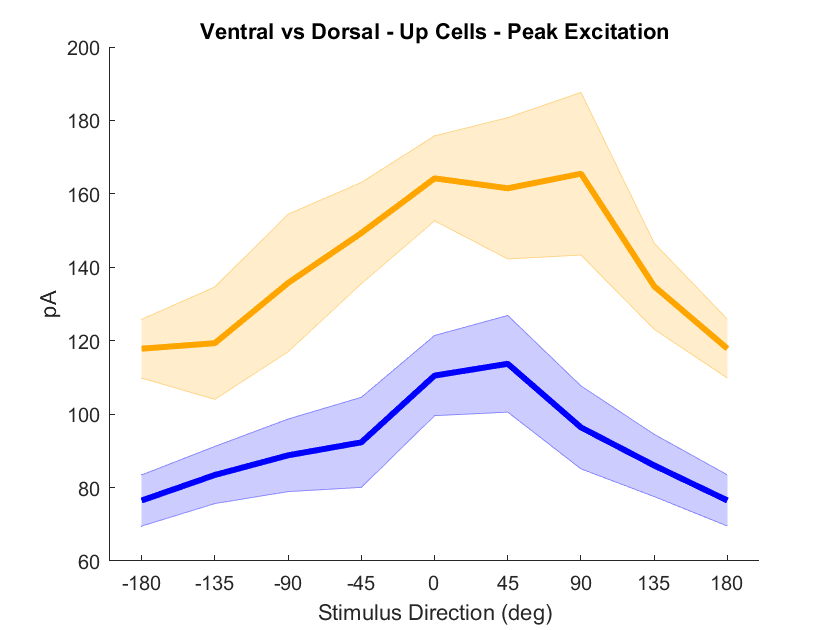

upPeakEx_Dorsal = upPeakEx(dt_upEx | dn_upEx, :);
upPeakEx_Ventral = upPeakEx(vn_upEx | vt_upEx, :);
downPeakEx_Dorsal = downPeakEx(dt_downEx | dn_downEx, :);
downPeakEx_Ventral = downPeakEx(vn_downEx | vt_downEx, :);

downPeakEx_avg = mean(downPeakEx);
upPeakEx_SE = SE_F(upPeakEx);
downPeakEx_SE = SE_F(downPeakEx);

upPeakEx_Dorsal_avg = mean(upPeakEx_Dorsal);
upPeakEx_Dorsal_SE = SE_F(upPeakEx_Dorsal);
upPeakEx_Ventral_avg = mean(upPeakEx_Ventral);
upPeakEx_Ventral_SE = SE_F(upPeakEx_Ventral);
downPeakEx_Dorsal_avg = mean(downPeakEx_Dorsal);
downPeakEx_Dorsal_SE = SE_F(downPeakEx_Dorsal);
downPeakEx_Ventral_avg = mean(downPeakEx_Ventral);
downPeakEx_Ventral_SE = SE_F(downPeakEx_Ventral);

allPeakEx_Dorsal_avg = mean([upPeakEx_Dorsal; downPeakEx_Dorsal(:, [5:8, 1:4])]);
allPeakEx_Dorsal_SE = SE_F([upPeakEx_Dorsal; downPeakEx_Dorsal(:, [5:8, 1:4])]);
allPeakEx_Ventral_avg = mean([upPeakEx_Ventral; downPeakEx_Ventral(:, [5:8, 1:4])]);
allPeakEx_Ventral_SE = SE_F([upPeakEx_Ventral; downPeakEx_Ventral(:, [5:8, 1:4])]);

xAxis = [-180:45:180];
figure
title('Ventral vs Dorsal - Up Cells - Peak Excitation')
hold on
shadedErrorBar(xAxis, -upPeakEx_Ventral_avg(orientationOrderUp), upPeakEx_Ventral_SE(orientationOrderUp), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, -upPeakEx_Dorsal_avg(orientationOrderUp), upPeakEx_Dorsal_SE(orientationOrderUp), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('pA')
xticks([-180:45:180])

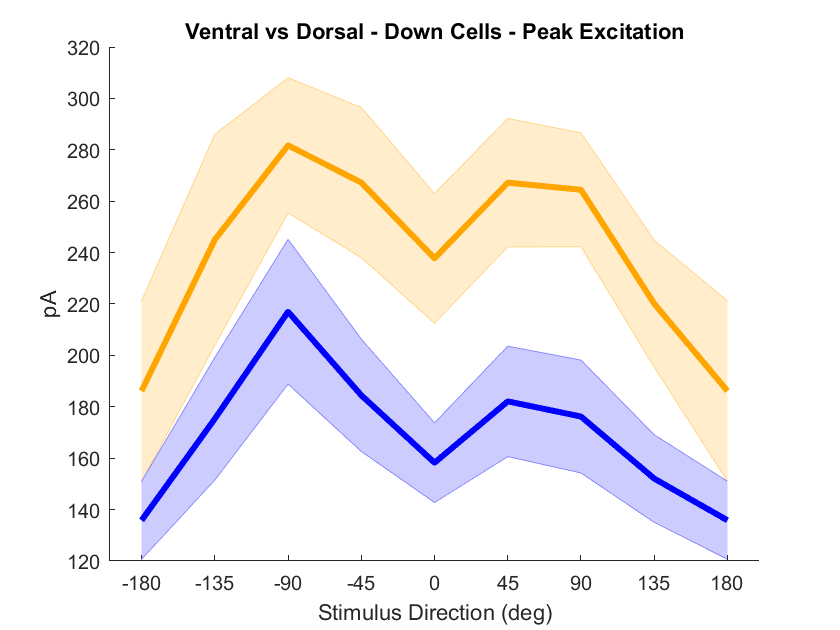


figure
title('Ventral vs Dorsal - Down Cells - Peak Excitation')
hold on
shadedErrorBar(xAxis, -downPeakEx_Ventral_avg(orientationOrderDown), downPeakEx_Ventral_SE(orientationOrderDown), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, -downPeakEx_Dorsal_avg(orientationOrderDown), downPeakEx_Dorsal_SE(orientationOrderDown), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('pA')
xticks([-180:45:180])

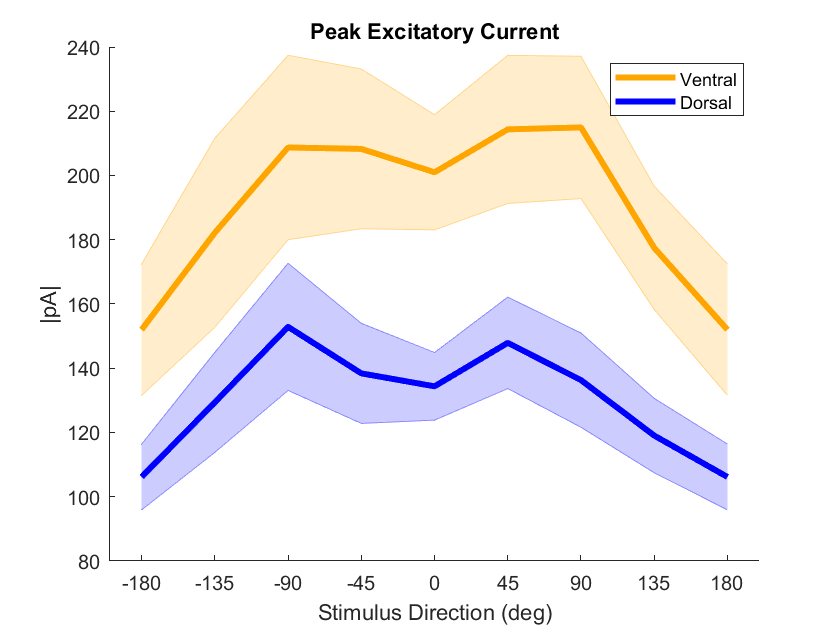


figure
title('Peak Excitatory Current') %Ventral vs Dorsal - All Cells - Peak Excitation
hold on
shadedErrorBar(xAxis, -allPeakEx_Ventral_avg(orientationOrderUp), allPeakEx_Ventral_SE(orientationOrderUp), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, -allPeakEx_Dorsal_avg(orientationOrderUp), allPeakEx_Dorsal_SE(orientationOrderUp), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('|pA|')
xticks([-180:45:180])
legend('Ventral', 'Dorsal')

## DSIs of Excitation

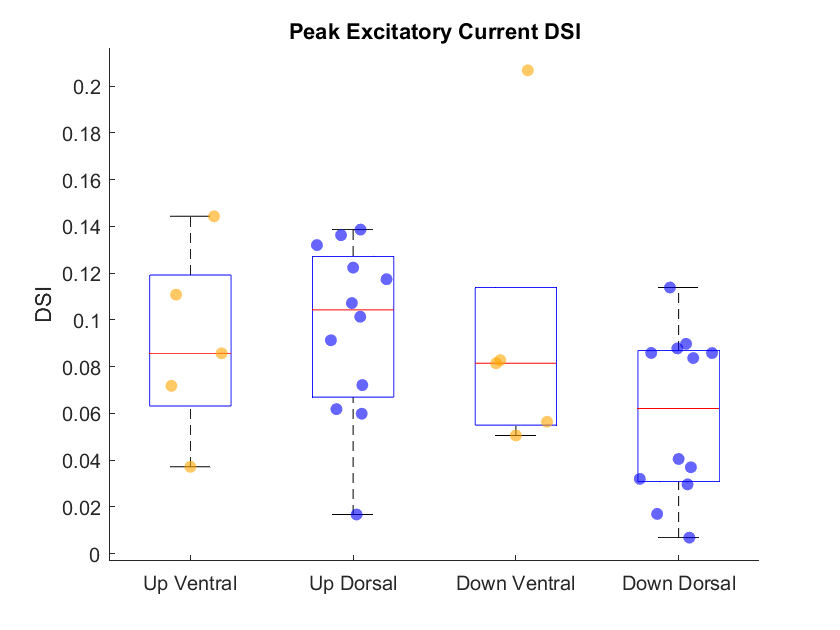


%vectorize every category in a cell array
vectorizedResponses = {upPeakEx_Dorsal, upPeakEx_Ventral, downPeakEx_Dorsal, downPeakEx_Ventral};
vectorizedDSIs = cell(1, size(vectorizedResponses, 2));
for i = 1:size(vectorizedResponses, 2)
    m_i = -vectorizedResponses{i};
    currentDSIs = zeros(size(m_i, 1), 1);
    for j = 1:size(m_i, 1)
        currentDSIs(j) = calculateDSI(orientations, m_i(j, :));
    end
    vectorizedDSIs{i} = currentDSIs;
end
upPeakEx_Dorsal_DSI = vectorizedDSIs{1};
upPeakEx_Ventral_DSI = vectorizedDSIs{2};
downPeakEx_Dorsal_DSI = vectorizedDSIs{3};
downPeakEx_Ventral_DSI = vectorizedDSIs{4};

allPoints = [upPeakEx_Ventral_DSI; upPeakEx_Dorsal_DSI; downPeakEx_Ventral_DSI; downPeakEx_Dorsal_DSI];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(upPeakEx_Ventral_DSI); indx2 = indx1 + numel(upPeakEx_Dorsal_DSI);
indx3 = indx2 + numel(downPeakEx_Ventral_DSI);
groupIDs(indx1 + 1:indx2) = 1;
groupIDs(indx2 + 1:indx3) = 2;
groupIDs(indx3 + 1:end) = 3;


figure
title ('Peak Excitatory Current DSI')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upPeakEx_Ventral_DSI)), upPeakEx_Ventral_DSI,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(upPeakEx_Dorsal_DSI))+1, upPeakEx_Dorsal_DSI,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakEx_Ventral_DSI))+2, downPeakEx_Ventral_DSI,'filled','MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakEx_Dorsal_DSI))+3, downPeakEx_Dorsal_DSI,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Up Ventral', 'Up Dorsal', 'Down Ventral', 'Down Dorsal'})
ylabel('DSI')
box off

## Inhibitory Currents

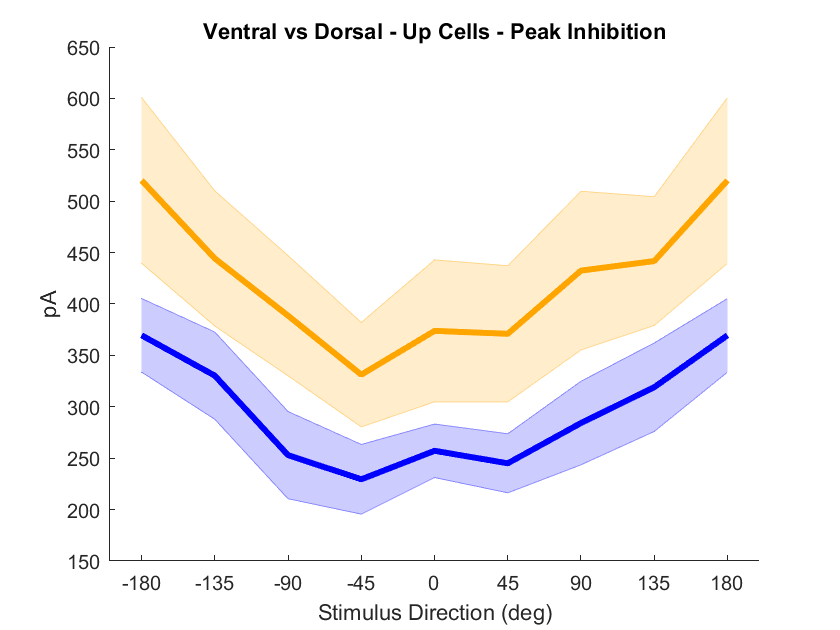

upPeakInh_Dorsal = upPeakInh(dt_upInh | dn_upInh, :);
upPeakInh_Ventral = upPeakInh(vn_upInh | vt_upInh, :);
downPeakInh_Dorsal = downPeakInh(dt_downInh | dn_downInh, :);
downPeakInh_Ventral = downPeakInh(vn_downInh | vt_downInh, :);

downPeakInh_avg = mean(downPeakInh);
upPeakInh_SE = SE_F(upPeakInh);
downPeakInh_SE = SE_F(downPeakInh);

upPeakInh_Dorsal_avg = mean(upPeakInh_Dorsal);
upPeakInh_Dorsal_SE = SE_F(upPeakInh_Dorsal);
upPeakInh_Ventral_avg = mean(upPeakInh_Ventral);
upPeakInh_Ventral_SE = SE_F(upPeakInh_Ventral);
downPeakInh_Dorsal_avg = mean(downPeakInh_Dorsal);
downPeakInh_Dorsal_SE = SE_F(downPeakInh_Dorsal);
downPeakInh_Ventral_avg = mean(downPeakInh_Ventral);
downPeakInh_Ventral_SE = SE_F(downPeakInh_Ventral);

allPeakInh_Dorsal_avg = mean([upPeakInh_Dorsal; downPeakInh_Dorsal(:, [5:8, 1:4])]);
allPeakInh_Dorsal_SE = SE_F([upPeakInh_Dorsal; downPeakInh_Dorsal(:, [5:8, 1:4])]);
allPeakInh_Ventral_avg = mean([upPeakInh_Ventral; downPeakInh_Ventral(:, [5:8, 1:4])]);
allPeakInh_Ventral_SE = SE_F([upPeakInh_Ventral; downPeakInh_Ventral(:, [5:8, 1:4])]);

xAxis = [-180:45:180];
figure
title('Ventral vs Dorsal - Up Cells - Peak Inhibition')
hold on
shadedErrorBar(xAxis, upPeakInh_Ventral_avg(orientationOrderUp), upPeakInh_Ventral_SE(orientationOrderUp), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, upPeakInh_Dorsal_avg(orientationOrderUp), upPeakInh_Dorsal_SE(orientationOrderUp), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('pA')
xticks([-180:45:180])

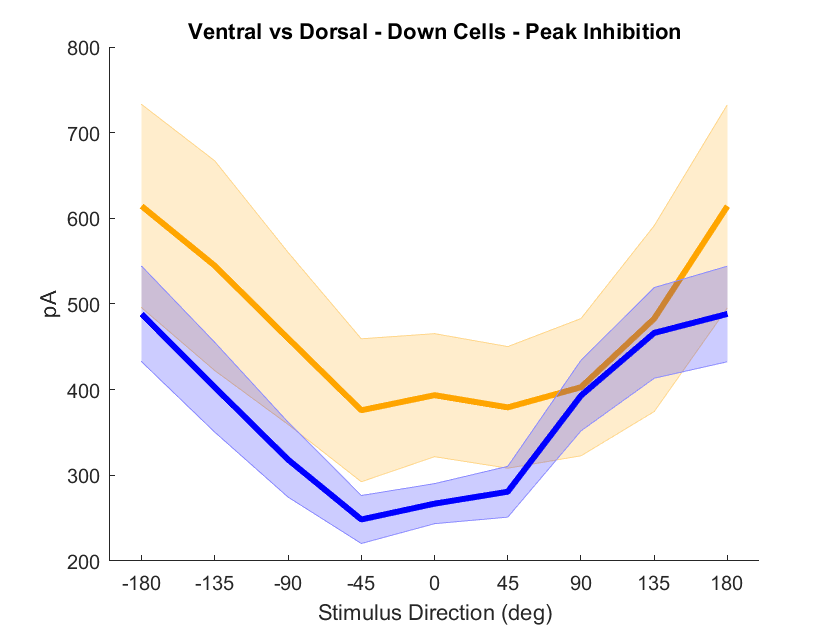


figure
title('Ventral vs Dorsal - Down Cells - Peak Inhibition')
hold on
shadedErrorBar(xAxis, downPeakInh_Ventral_avg(orientationOrderDown), downPeakInh_Ventral_SE(orientationOrderDown), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, downPeakInh_Dorsal_avg(orientationOrderDown), downPeakInh_Dorsal_SE(orientationOrderDown), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('pA')
xticks([-180:45:180])

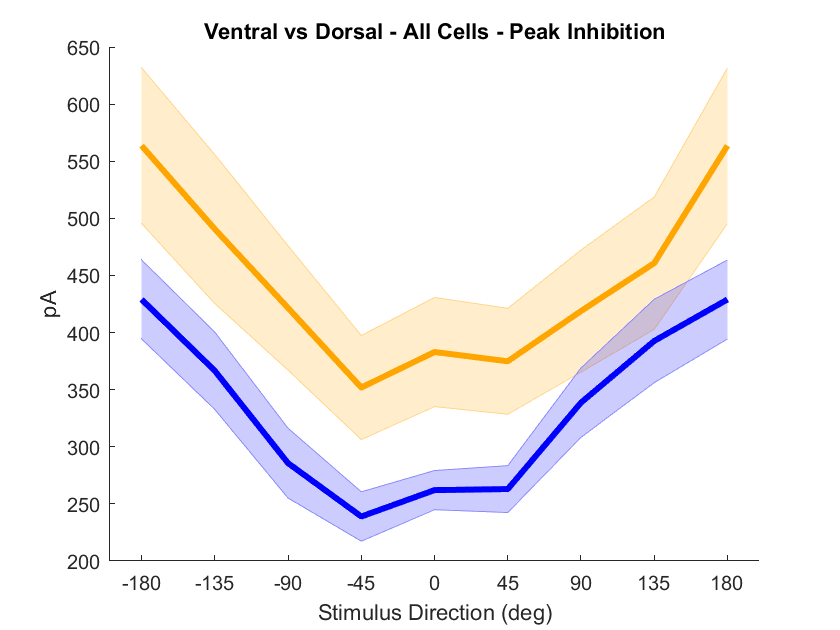


figure
title('Ventral vs Dorsal - All Cells - Peak Inhibition')
hold on
shadedErrorBar(xAxis, allPeakInh_Ventral_avg(orientationOrderUp), allPeakInh_Ventral_SE(orientationOrderUp), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(xAxis, allPeakInh_Dorsal_avg(orientationOrderUp), allPeakInh_Dorsal_SE(orientationOrderUp), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('Stimulus Direction (deg)')
ylabel('pA')
xticks([-180:45:180])

## DSIs of Inhibition

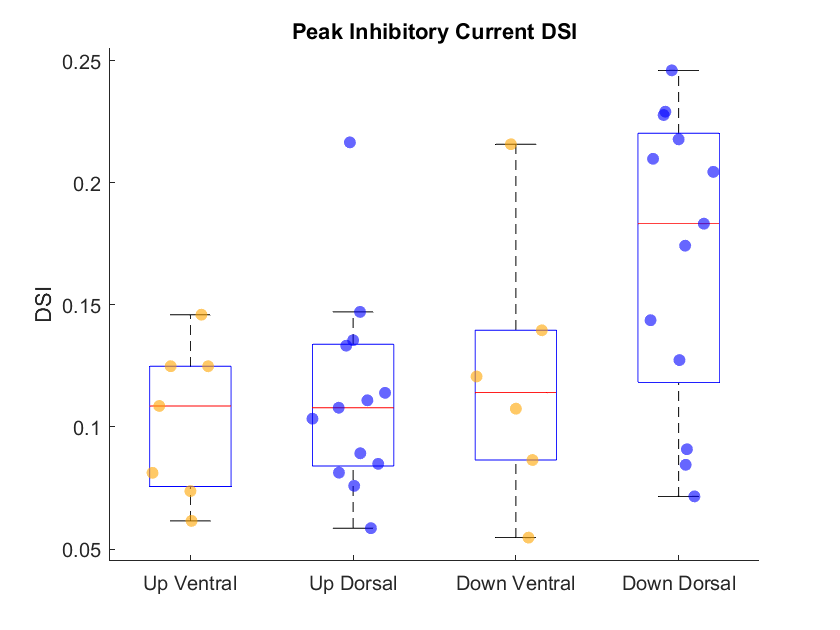

%vectorize every category in a cell array
vectorizedResponses = {upPeakInh_Dorsal, upPeakInh_Ventral, downPeakInh_Dorsal, downPeakInh_Ventral};
vectorizedDSIs = cell(1, size(vectorizedResponses, 2));
for i = 1:size(vectorizedResponses, 2)
    m_i = vectorizedResponses{i};
    currentDSIs = zeros(size(m_i, 1), 1);
    for j = 1:size(m_i, 1)
        currentDSIs(j) = calculateDSI(orientations, m_i(j, :));
    end
    vectorizedDSIs{i} = currentDSIs;
end
upPeakInh_Dorsal_DSI = vectorizedDSIs{1};
upPeakInh_Ventral_DSI = vectorizedDSIs{2};
downPeakInh_Dorsal_DSI = vectorizedDSIs{3};
downPeakInh_Ventral_DSI = vectorizedDSIs{4};

allPoints = [upPeakInh_Ventral_DSI; upPeakInh_Dorsal_DSI; downPeakInh_Ventral_DSI; downPeakInh_Dorsal_DSI];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(upPeakInh_Ventral_DSI); indx2 = indx1 + numel(upPeakInh_Dorsal_DSI);
indx3 = indx2 + numel(downPeakInh_Ventral_DSI);
groupIDs(indx1 + 1:indx2) = 1;
groupIDs(indx2 + 1:indx3) = 2;
groupIDs(indx3 + 1:end) = 3;


figure
title ('Peak Inhibitory Current DSI')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upPeakInh_Ventral_DSI)), upPeakInh_Ventral_DSI,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(upPeakInh_Dorsal_DSI))+1, upPeakInh_Dorsal_DSI,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakInh_Ventral_DSI))+2, downPeakInh_Ventral_DSI,'filled','MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakInh_Dorsal_DSI))+3, downPeakInh_Dorsal_DSI,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Up Ventral', 'Up Dorsal', 'Down Ventral', 'Down Dorsal'})
ylabel('DSI')
box off